# Physics Informed Neural Networks for Numerical Analysis

*Robin Pfeiffer*

*Supervised by Dr. Niall Madden*

*June 2022*

## 1. Introduction

Multilayered artificial neural networks are becoming a very useful tool in many application fields, including in numerical solution of differential equations. This is a report on the work I have completed over the summer of 2022, supervised by Niall Madden, exploring the setup of neural networks and some of its uses in the real world.

## 2. How Neural Networks work

In its simplest form, a neural network is just a function. Given some '*training data*', i.e., some inputs and their desired output, we want to make this function give us the desired output given those specific inputs. We can then use the function on new points to see what its predicted output is.

There is a general form that most networks follow. It is set up in layers, with some number of neurons per layer. In order to go from one layer to another, we left multiply our values by a weight matrix, and add a bias. Through this process, we end up with many of variables. Training our network consists of making small changes to these variables over time, until we are happy with the output.

### 2.1 Activation Function

The artificial neural network approach uses repeated application of a simple, nonlinear function. In this case, we chose to base our neural network on the sigmoid function,


$$\sigma(x) = \frac{1}{1+e^{-x}$$


It is quite a simple function; all we can do is change how quickly it increases from zero to one, and at what point along the $x$-axis it does so, which is done by scaling or shifting the input variable, $x$. However, by chaining multiple instances of these functions together, we can create some more complex functions, as will be shown in later sections.

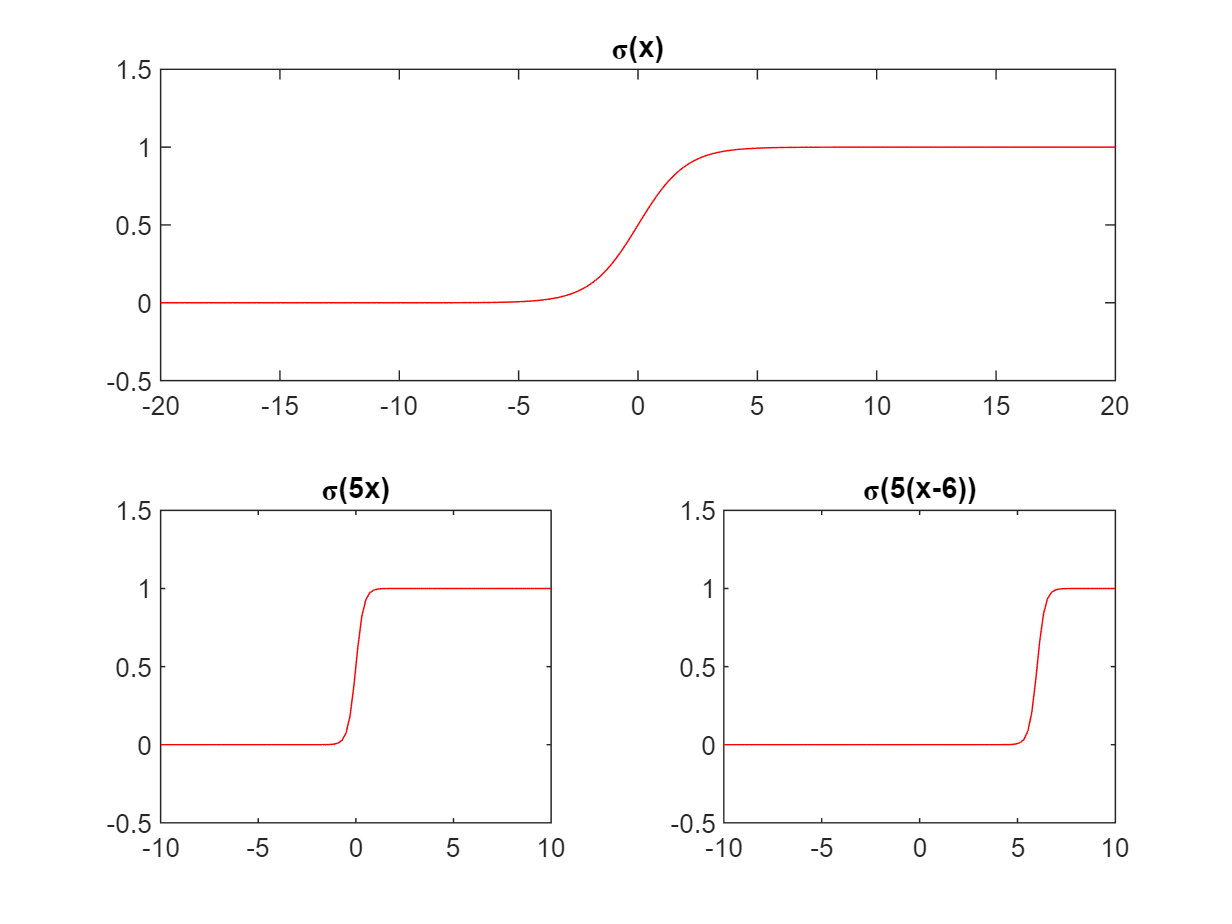

clear;

x = linspace(-20,20,200);
figure;
tiledlayout(2, 2)

nexttile([1 2])
plot(x, 1./(1+exp(-x)), 'r-')
xlim([-20 20]), ylim([-0.5 1.5])
title('\sigma(x)')

nexttile
plot(x, 1./(1+exp(-(5*x))), 'r-')
xlim([-10 10]), ylim([-0.5 1.5])
title('\sigma(5x)')

nexttile
plot(x, 1./(1+exp(-(5*(x-6)))), 'r-');
xlim([-10 10]), ylim([-0.5 1.5])
title('\sigma(5(x-6))')

It is also possible to have a vector based sigmoid function. If your input is a vector of size n, your output will be a vector of size n. 

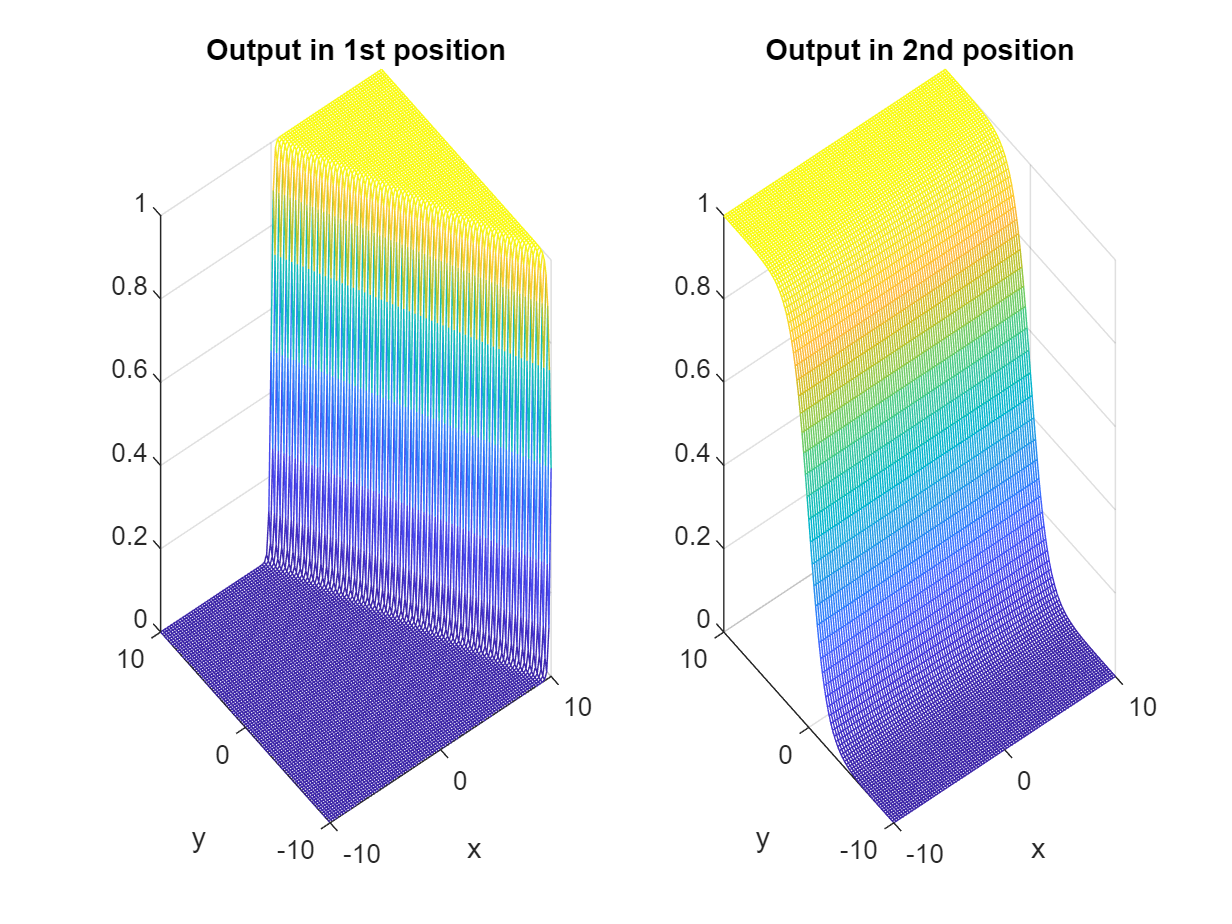

xvals = linspace(-10,10,101); yvals = xvals;
W = [10,5; 0,1];
b = [-50;0];
for k1 = 1:101
    xk = xvals(k1);
    for k2 = 1:101
        yk = yvals(k2);
        xy = [xk;yk];
        a2 = activate(xy,W,b);
        Aval(k2,k1) = a2(1);
        Bval(k2,k1) = a2(2);
    end
end
[X1,Y1] = meshgrid(xvals,yvals);
figure; tiledlayout(1,2)
nexttile
mesh(X1,Y1,Aval)
xlabel("x"), ylabel("y")
title("Output in 1st position")
nexttile
mesh(X1,Y1,Bval)
xlabel("x"), ylabel("y")
title("Output in 2nd position")

### 2.2 More general activation functions

One limitation of the sigmoid function is that it is bounded between 0 and 1. If we are dealing with negative number, we can replace it with the tanh function, which is bounded between -1 and 1. This makes the training process a bit harder however, as the derivative is harder to calculate.

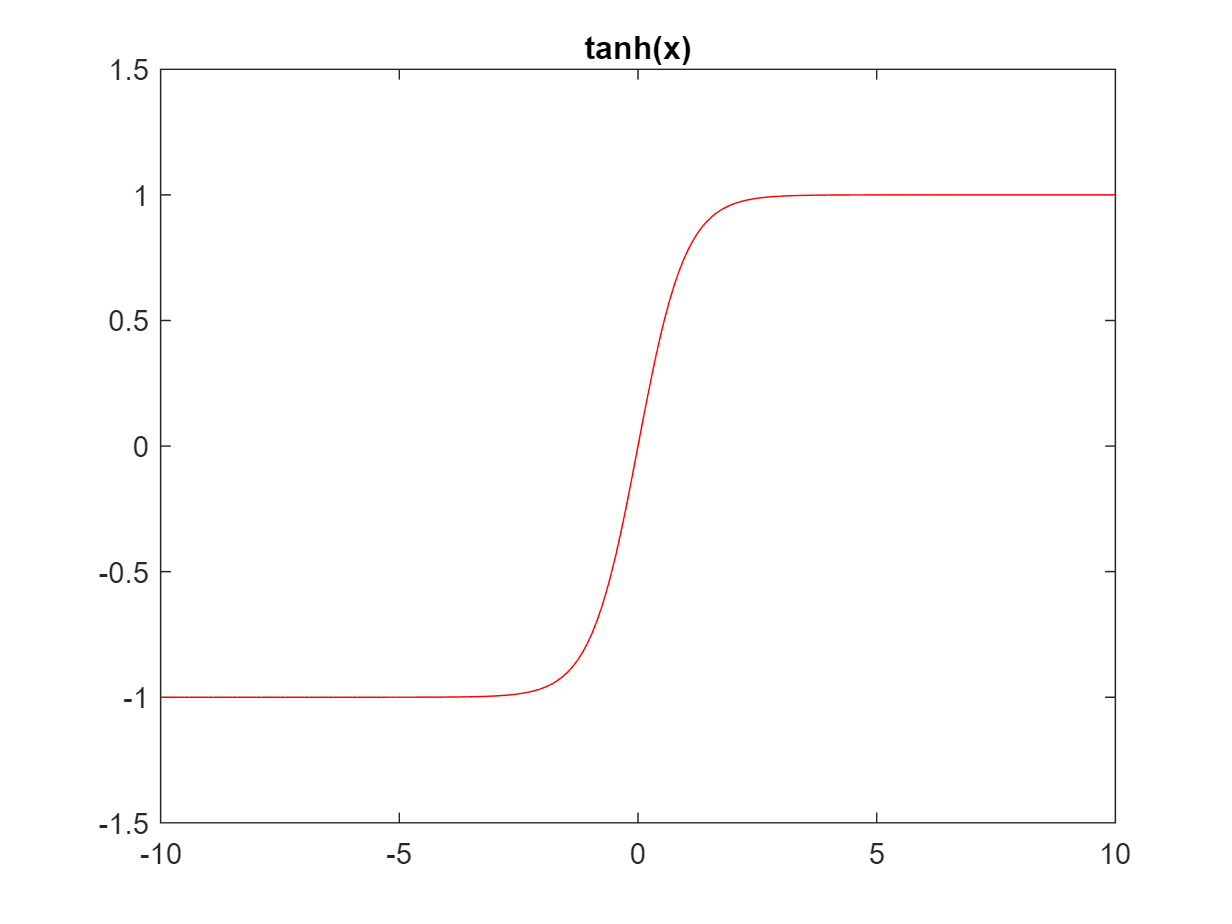

x = linspace(-10,10,200);
figure
plot(x, [exp(x)-exp(-x)]./[exp(x)+exp(-x)], 'r-');
xlim([-10 10]), ylim([-1.5 1.5])
title('tanh(x)')

### 2.3 Setup of Neural Network

A neural network is built on multiple layers, with multiple nodes in each layer. The first layer is our input, the final layer is our output, and the middle layers are what we call hidden layers. 

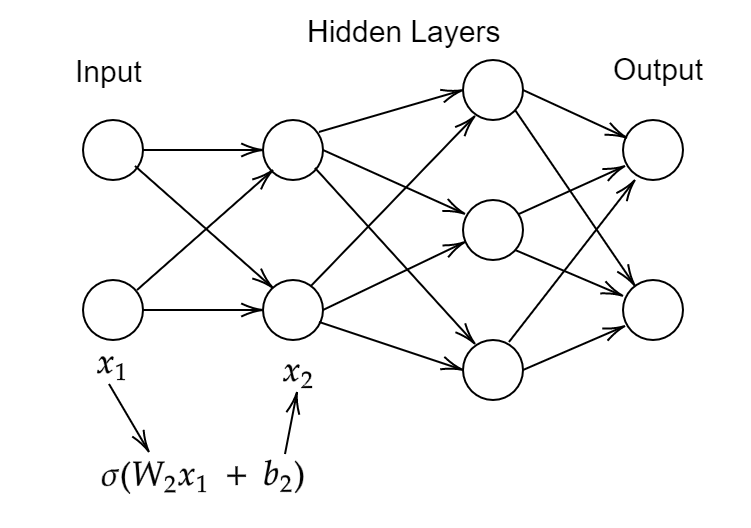

In order to go from one layer to another, we first multiply it by a matrix of weights **W** and add some bias **b**, and then run it through our activation function. 


$$\textbf{x}_2 = \sigma ( \textbf{W}_2\cdot\textbf{x}_1 + \textbf{b}_2)$$


The size of each weight matrix and bias is determined by the number of neurons in the layer before and after. If there's $n$ variables in the first layer and $m$ variables in the second, our weight will be an $m \times n$ matrix. The bias will be a vector of size $m$.

In this case, $x_1$, $x_2
$, $b_2$ are vectors of size 2, and $W_2$ is a matrix of size $2 \times 2$.

We now have a function $f(x):\mathbb{R}^2 \rightarrow \mathbb{R}^2$ that symbolises our neural network. We let **X** be the input of our training data, and **Y** the required output. We can now create a measure for how close our network is to the required solution. We let the cost function be

 
$$Cost = \frac{1}{N} \sum_{i=1}^N\frac{1}{2}||y(x^{\{i\}})-f(x^{\{i\}})||^2$$


Note: This is a function of the weights and biases in the neural network.

We now need to minimise this cost function, by changing the weights and biases in our network.

### 2.4 Stochastic Gradient Descent

To see how the gradient descent method works on our cost function, we will explore how it works on this simpler, two-dimensional function.

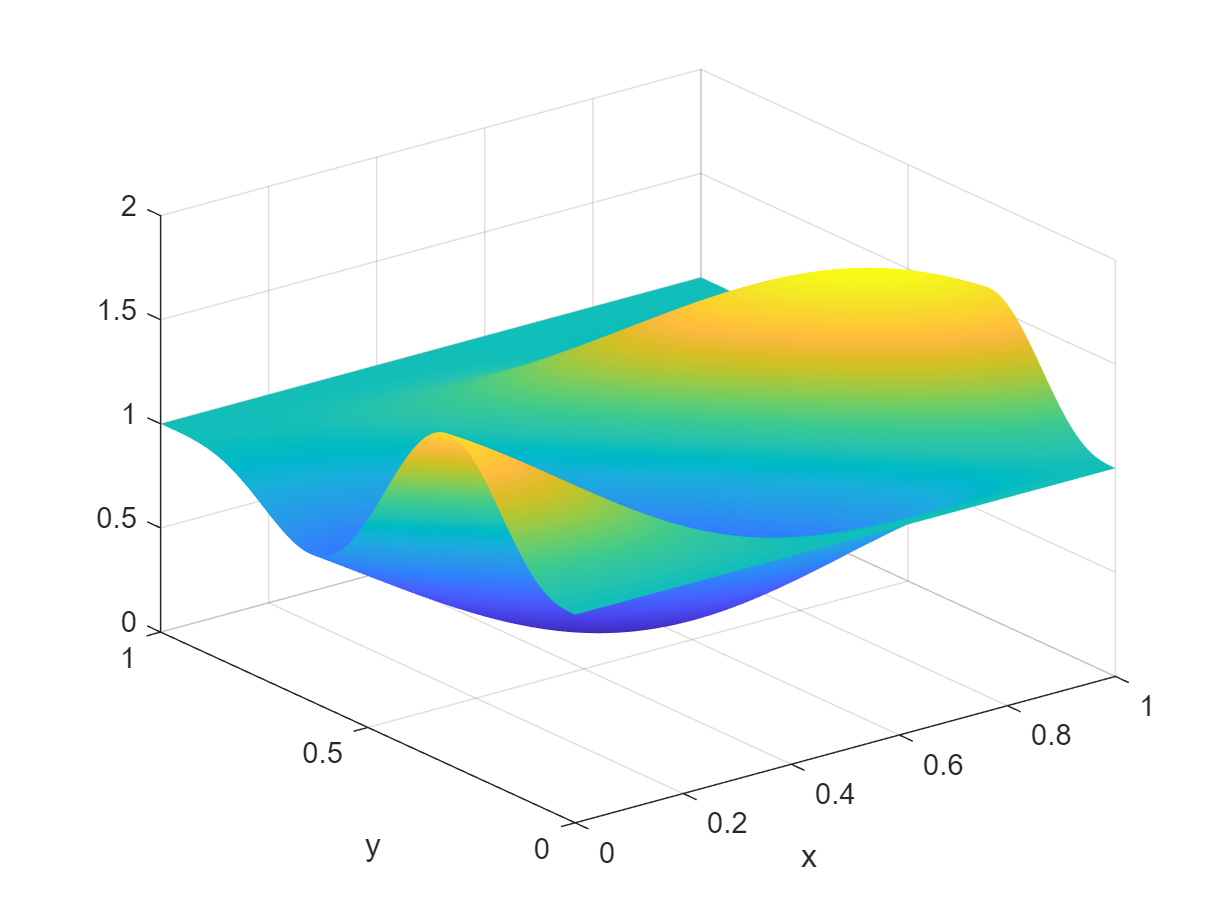

f = chebfun2(@(x,y) 1+20*y.^2.*(1-y).^3.*sin(2*pi*(x+y)), [0 1 0 1]);
plot(f); xlabel('x');  ylabel('y')

This function has a minimum on 0.3088 at $(0.35, 0.4)$

[m, X]=min2(f)

m = 0.3088

X =     0.3500    0.4000


The idea of Gradient Descent is that, if $x_{(i-1)}$ is an estimate for $x_\min$, then

$x_{(i)} = x_{(i-1)} - \eta \nabla f$ should be an even better one, for some $\eta$ (which depends on the situation)

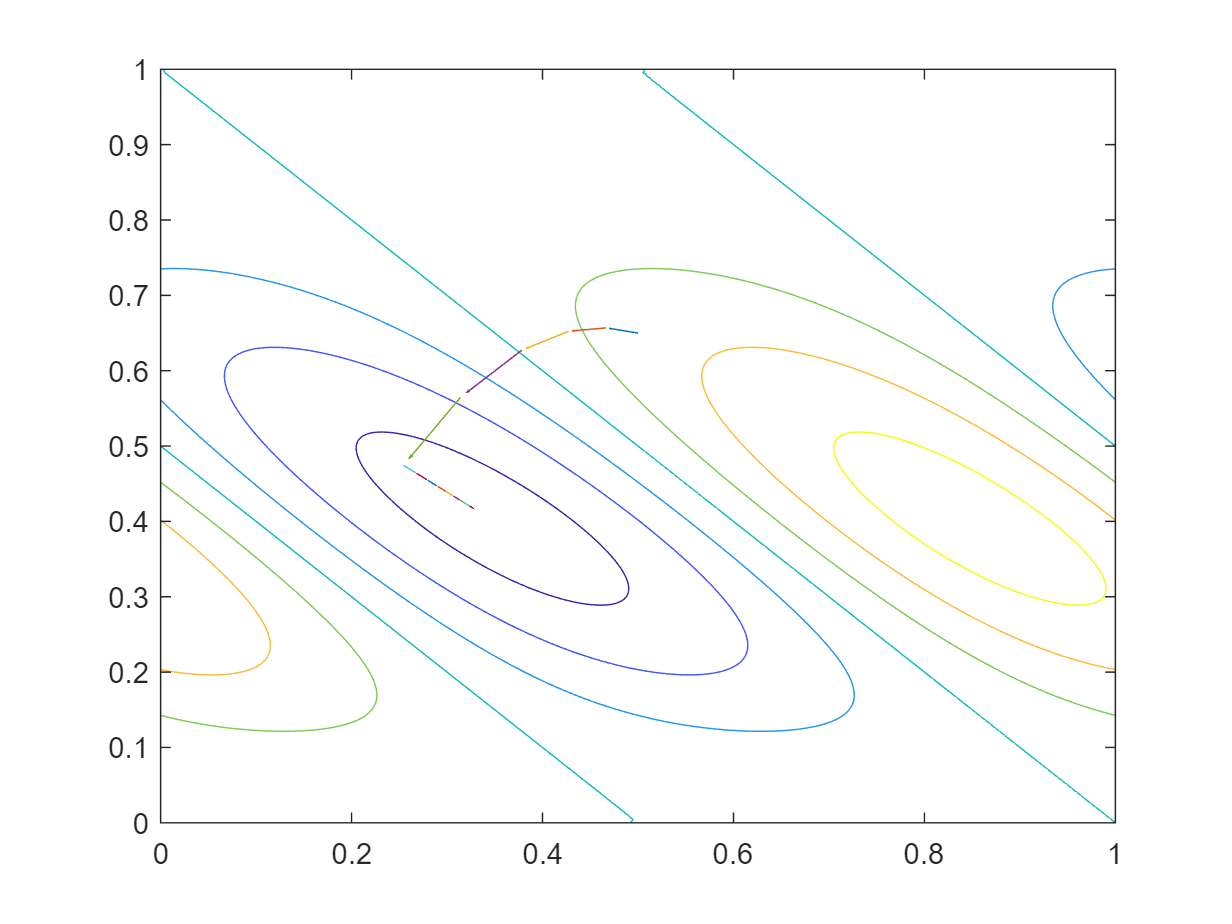

Df = grad(f);

x0=[.5;.65];
N = 15;
eta = 0.025;
x = zeros(2,N);
x(:,1)=x0;
figure;
contour(f); hold on;
for i=2:N
   x(:,i) = x(:,i-1) - eta*Df(x(1,i-1), x(2,i-1));
   dx = x(:,i)-x(:,i-1);
   quiver(x(1,i-1), x(2,i-1), dx(1), dx(2))
end
hold off;

xlim([0.00 1.00])
ylim([0.00 1.00])

Each of these arrows moves in the direction of greatest descent (along the total derivative)

However, it can be very expensive to find the derivative in all variables, so we just update our function one variable at a time. Our new formula will look like $x_{(i)} = x_{(i-1)} - \eta (\nabla f)_k$, for a randomly chosen k.

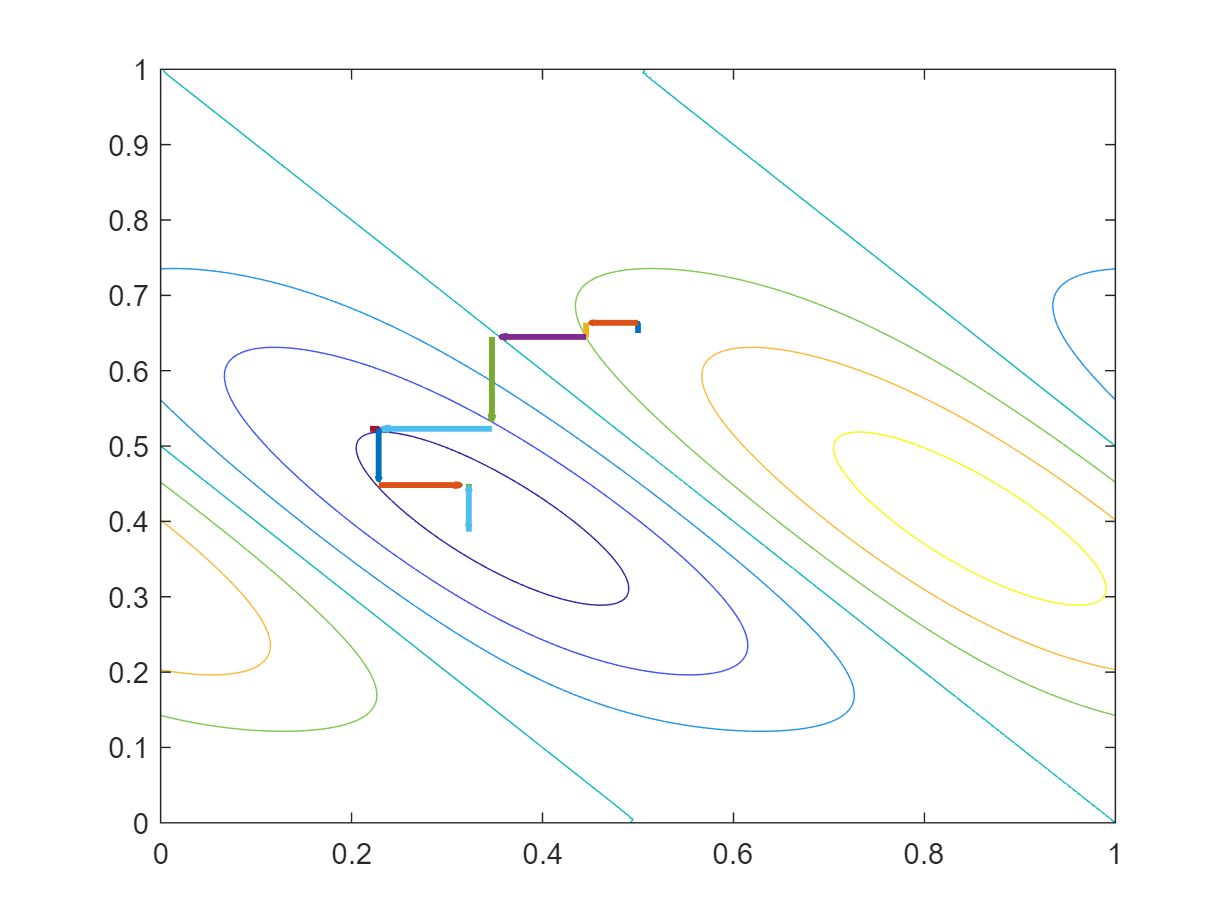

rng(200)

N = 14;
eta = 0.05;
x = zeros(2,N);
x0 = [0.5,0.65];
x(:,1)=x0;
figure(4);
contour(f); hold on;
for i=2:N
   k = randi(2);
   x(:,i) = x(:,i-1);
   df = Df(k);
   x(k,i) = x(k,i-1) - eta*df(x(1,i-1), x(2,i-1));
   dx = x(:,i)-x(:,i-1);
   quiver(x(1,i-1), x(2,i-1), dx(1), dx(2), 'linewidth', 2)
end
hold off;

Each step is in only one direction, either along the x-axis or the y-axis.

We can extend this idea to our cost function, with $p$ variables across $N$ layers. At each iteration we will do the following:

- Choose an integer $k$ between 1 and $p$

- Let $a_1 = k$

- $a_{i+1} = \sigma(W_{i+1} \cdot a_i+b_{i+1})$,         for $i = 2, 3, \dots, N$

- 
$$\delta_N = a_N(1-a_N)(a_N-Y(k))$$


- $\delta_i = a_i(1-a_i)(W_{i+1}\delta_{i+1})$            for $i = N-1, N-2, \dots, 2$

- 
$$W_i = W_i - \eta\cdot\delta_i\cdot a_i$$


- 
$$b_i = b_i - \eta \cdot \delta_i$$


$W_i$ and $b_i$ are the weight and bias used to jump from layer $i-1$ to $i$

After iterating over this many times, you should end up with a suitably small cost function. We can optimise this even further by changing your choice of $\eta$, more on this later.

## 3. Classification Problem

The following problem is posed as such. Given a region in $\mathbb{R}^2$, and two sets of points such as the figure below, train a neural network to split the region in two.

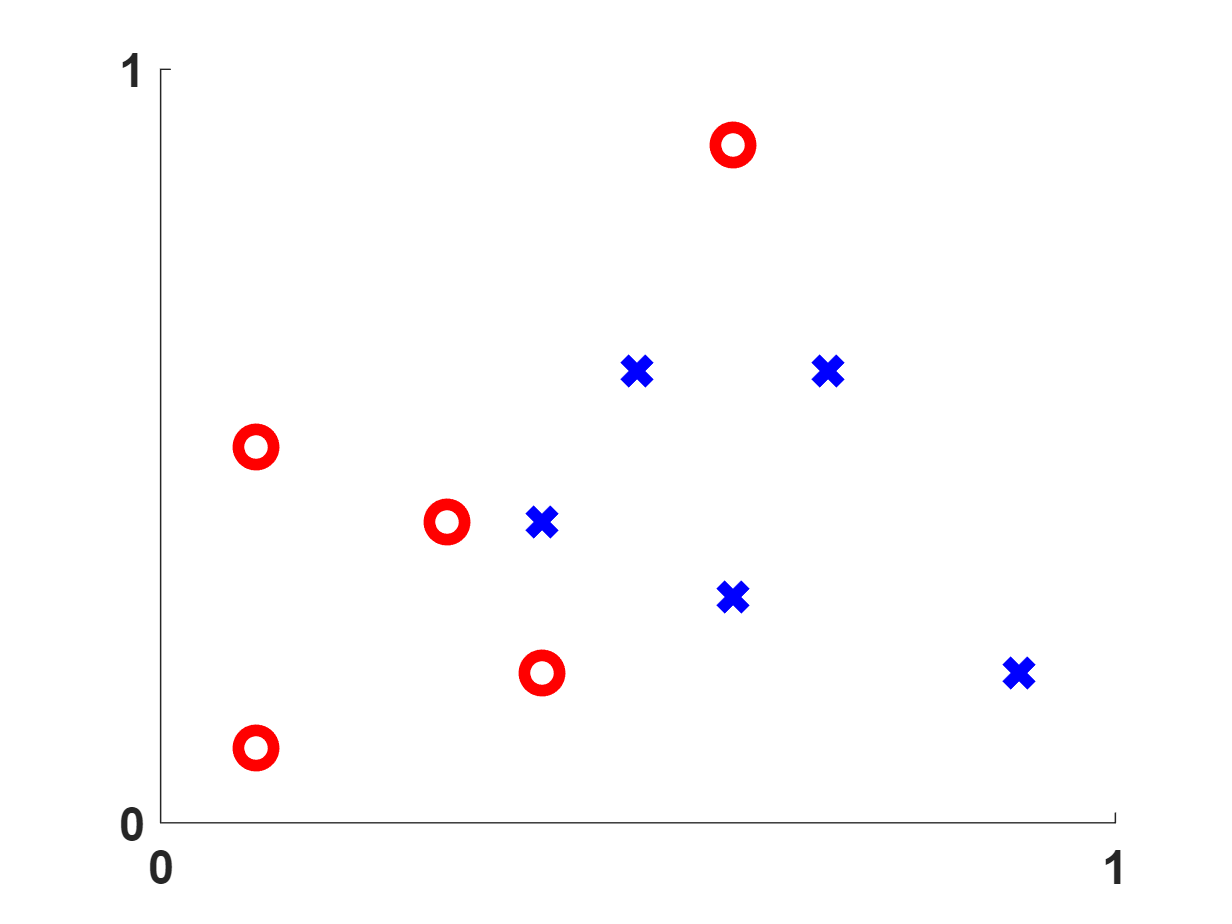

close all;

x1 = [0.1,0.3,0.1,0.6,0.4,0.6,0.5,0.9,0.4,0.7];
x2 = [0.1,0.4,0.5,0.9,0.2,0.3,0.6,0.2,0.4,0.6];
X = [x1;x2];
red_i = false(1,length(X));
red_i(1:5)=true;
blue_i = ~red_i;
Y = zeros(size(X));
Y(1,red_i)=1;
Y(2,blue_i)=1;
figure(5);
hold on;
plot(X(1,red_i), X(2,red_i),'ro', ...
   X(1,blue_i), X(2,blue_i),...
   'bx','MarkerSize',12,'LineWidth',4);
Axis1 = gca;
Axis1.XTick = [0 1]; Axis1.YTick = [0 1];
Axis1.FontWeight = 'Bold'; Axis1.FontSize = 16;
xlim([0,1])
ylim([0,1])
hold off;

We can very easily apply this problem to our neural network from above. We can construct our input matrix X out of the postition of each point, i.e., each column of $i$ will be $\left(\begin{array}{c} x_i\\y_i\end{array}\right)$. Our desired output for each point will be $0\\1$ if it is blue, $1\\0$ if it is red. Using this training data, we can train our network to give the following output.

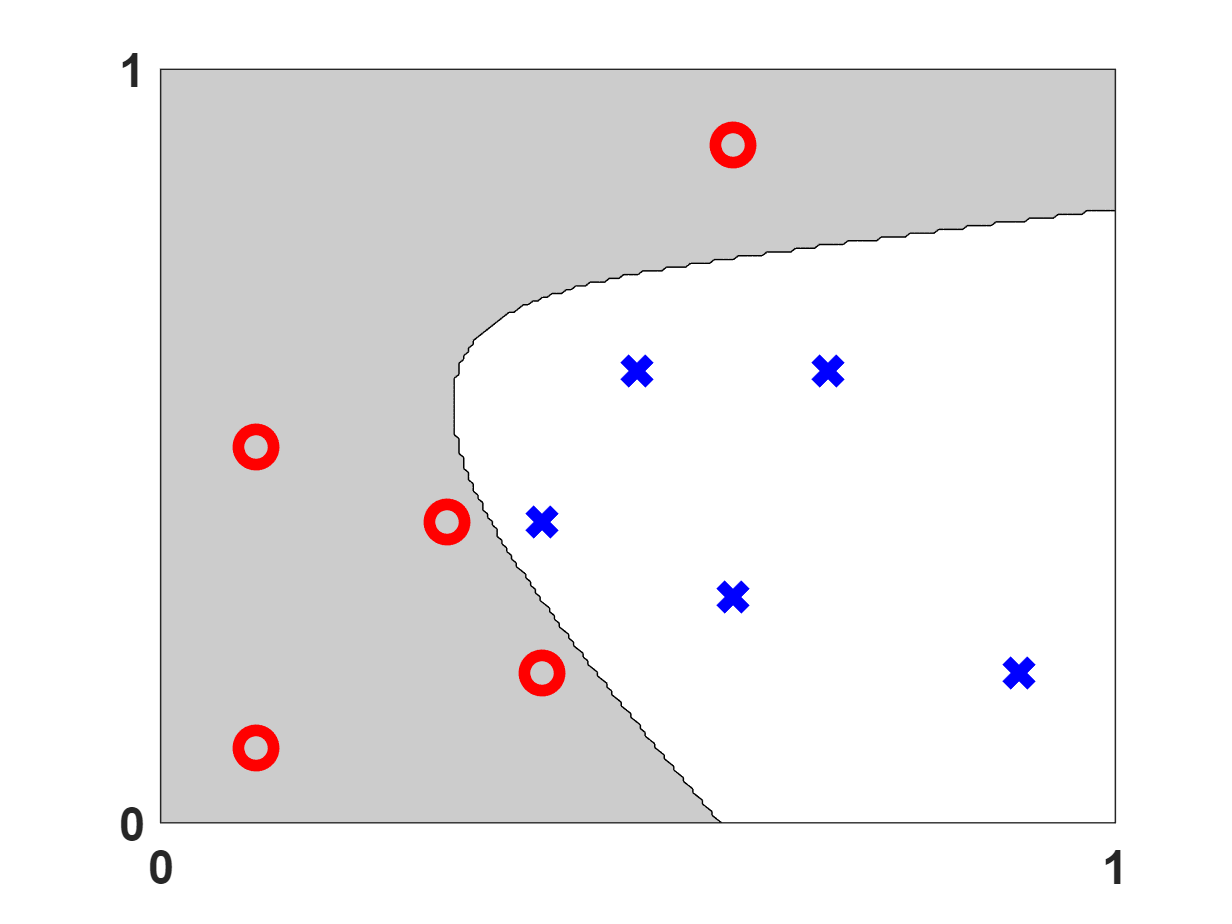

sgdV01

We now test this with a more complicated system, using the same neural network

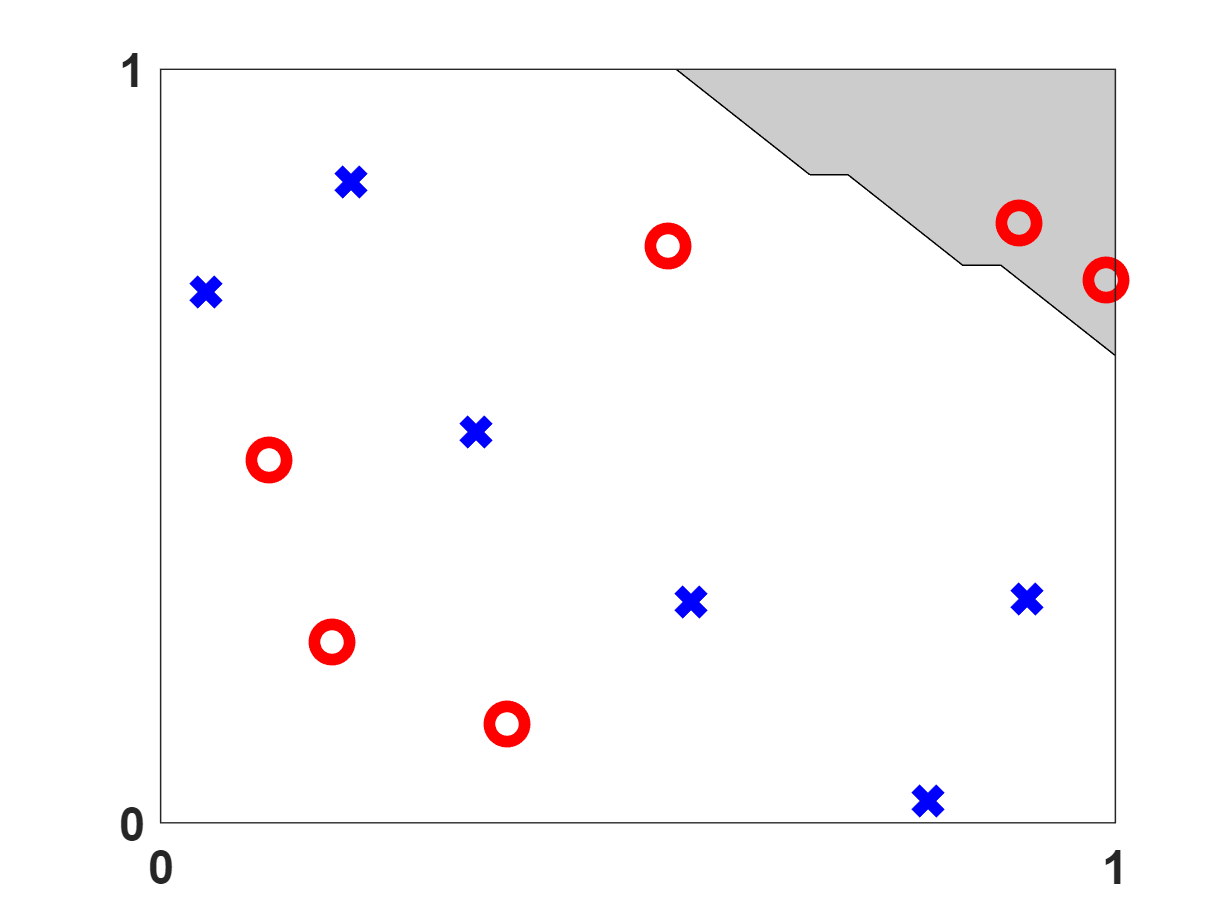

sgdV02([2 2 3 2]);

This clearly didn't go as planned. We can solve this by increasing the amount of layers, and the nuerons per layer

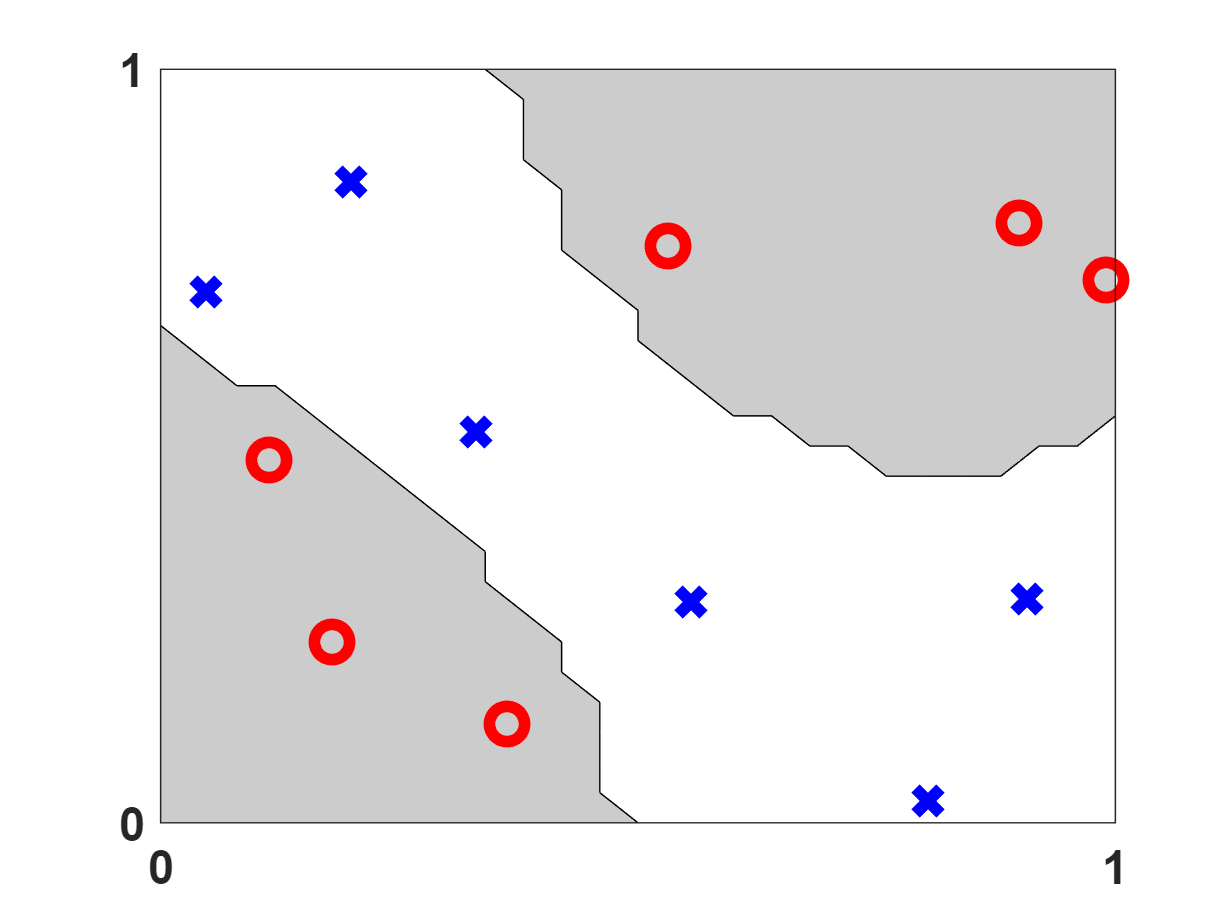

sgdV02([2 5 5 5 2]);

## 4. Applications to Numerical Analysis

We now move to the idea of a "Physics Informed Neural Network", called a "PINN" for short. At it's simplest, a PINN is just a neural network that is applied to some problem involving a mathematical model, such as a differential equation, and where the loss function is related to the residual. 

Since the solution of any differential equation is a function, we first look at the idea of approximating functions with neural networks.

### 4.1 Interpolation Problems

In numerical analysis, the process of *interpolation* means to find a function that agrees with a certain data set. For example, one might have five points $(x_0, y_0), \dots, (x_4, y_4)$, and we could compute the polynomial of degree 4, $p_4(x)$ that has the property that $p(x_i)=y_i$. This can be used in other applications. For example we could compute the value of the interpolant at some point not in the original set, or we could compute its derivative a a point, or its definite integral on some interval, etc.

 We can use the same setup to approximate functions, given only a few points that lie along it. The only slight change is we have one input, x position, and one output, which is our y position. Our cost function stays the same.

In the following example, it will try to plot the function $-\frac{1}{100}\frac{d^2u}{du^2} + u = (x>0.4)\land(x<0.6)$, using only the orange points as an input.

The points in this example are $(0,0),\ (0.1,0.02),\ (0.2, 0.05),\ (0.5, 0.63),\ (0.8, 0.06),\ (1,0)$

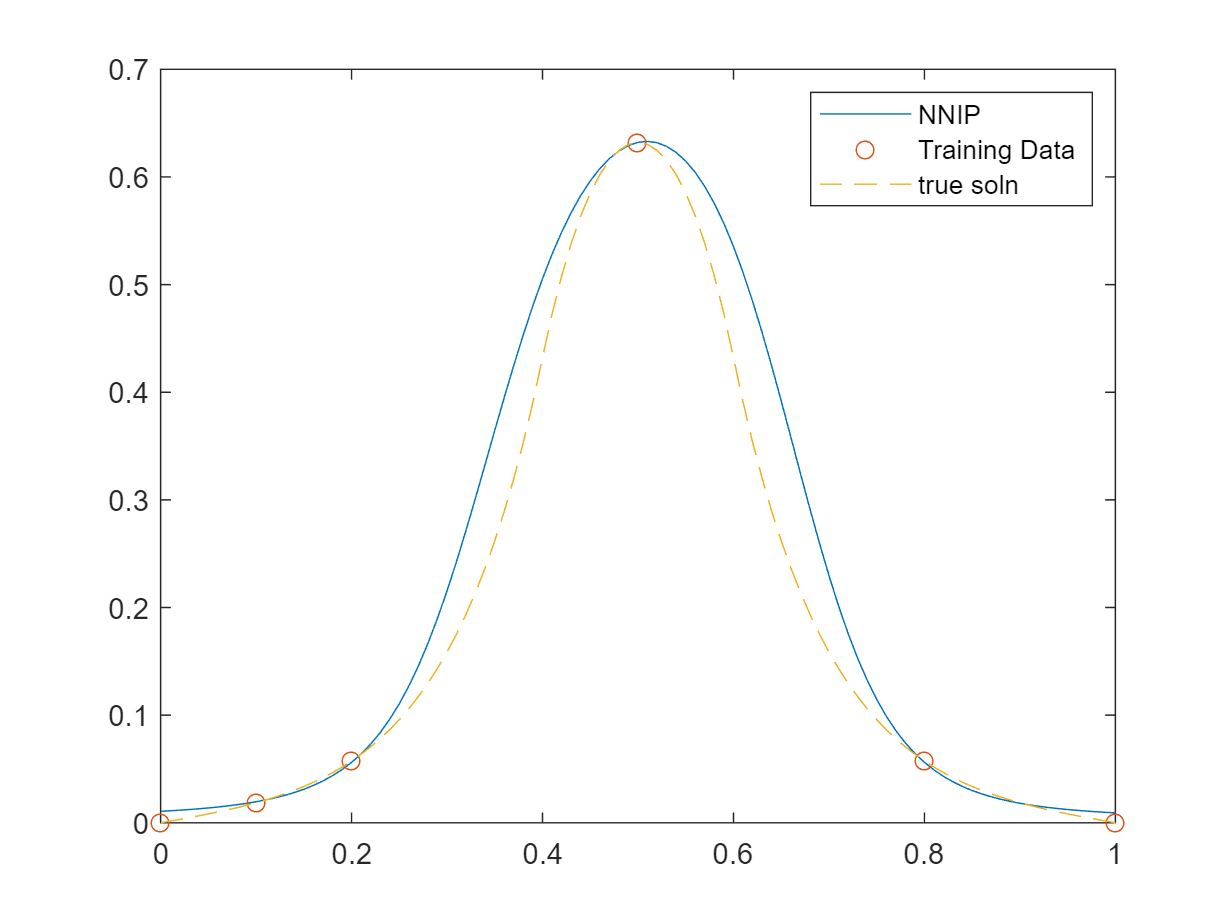

nlsrun_bvpV02

## 5. Physics Informed Neural Networks

PINNs are used in an almost identical way to solve differential equations. In this report we'll focus on first-order initial value problems. The differential equation can be written


$$D(u)(x) = 0 ~\text{ for }~ x>0,  \qquad ~\text{with}~u(0)=u_0$$


Here $D$ is a differential operator. In the followng example, we have taken


$$D(u) := 0.3\frac{du}{dx} + u(x)$$


and $u_0=1$.

Let's denote an approximate solution to this equation, given by a neural network, as $u^N$. Then the residual is $D_N:=D(u^N)(x_i)$, where the $x_i$ are the training points. So, if it were the case that $u^N(0)=u_0$ and $D_N\equiv 0$, then we have solved the problem exactly, at least at the initial point and training points. Morelikely, these are not zero, but they can be used to define the cost function


$$Costvec = [|D_N|, |u(0)-1|]$$


Our actual cost can now be $Cost = |Costvec|$

Now we have just another optimisation function. The results are as follows.


Solver stopped prematurely.

lsqnonlin stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1.700000e+03.

Nonlin solver did 94 iterations


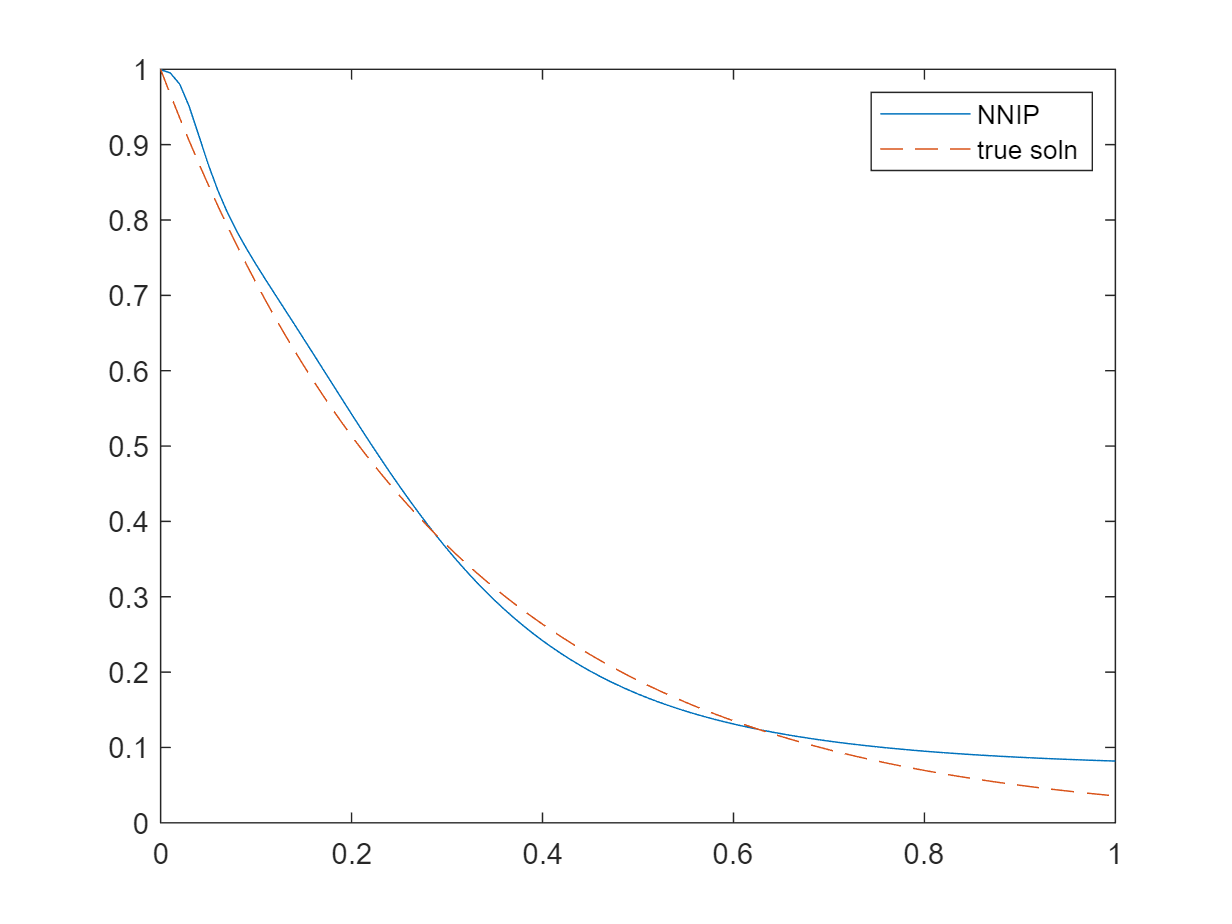

ComputeDerivativeExample

These results look promising, but there is scope for improvement, as we now discuss.

## 6. Optimisation

Then I looked at how to optimise the training of the network.

### 6.1 Stocastic Gradient Descent

Above I mentioned that using the stochastic gradient method is less expensive than using gradient descent. However, randomly choosing a point may not be the most optimal. Instead, what we could do is find the derivative in a few randomly chosen variables, and choose the biggest one. We can explore this by running both methods, and seeing how long it takes to reach a certain cost.

### 6.2 Number of Iterations

The number of iterations is directly linked to the program's runtime. We can significantly reduce the number of iterations by setting up a desired cost, and once we hit it we can stop. In my tests a good cost was $10^{-2}
$ as any improvements were negligible to the human eye. 

### 6.3 Choosing $\eta$

The value of $\eta$ also affects the runtime. If the value of $\eta$ is too small, it will take many steps to make any real progress. However, if it is too big, it could end up jumping around the minimum without getting any closer. The choice of $\eta$ is problem specific, and in the examples above $\eta = 1$ was used. 

It is also possible to change $\eta$ throughout the training process. At a certain point the steps wiil be too big, so you want to reduce it. I set my process up as follows. I set a goal for the network to reduce it's cost by 0.6% every 10,000 iterations, and if it missed the goal 3 times in a row, $\eta$ was reduced by 5%.

## 7. Conslusion

My work is based on Higham + Higham (2018) and Raissi (2019). This project allowed me to use the chebfun toolbox 

This is an area of maths that is quickly evolving and many new capabilities of neural networks are being discovered constantly, which is why it was exciting to work on this project.

If I had more time to work on this project, I would have liked to explore some other differential equations such as boundary value problems, coupled systems, non-linear problems and problems with noisy data. I would have also worked on a gradient descent solver for the differential equation instead of using a built-in non-linear solver. I would have also liked to develop my code in python to be shared more easily

### 7.1 References

Higham, C. F. and Higham, D. J. (2019) Deep learning: an introduction for applied mathematicians. SIAM Review, 61(4), pp. 860-891. (doi: 10.1137/18M1165748)

Raissi, P. Perdikaris, G.E. Karniadakis, (2019). Physics-informed neural networks: A deep learning framework for solving forward and inverse problems involving nonlinear partial differential equations. J. Comp Phys 37, pp686-707. (doi: [10.1016/j.jcp.2018.10.045](https://doi.org/10.1016/j.jcp.2018.10.045)).